# Offline RL for GBWM — Week 3: Shaped Reward + More Episodes + Multi-Window Eval

% Three minor changes over the Week 2 baseline:
%   (1) Dense per-step log-return reward + terminal goal bonus    (FinRL §3.2)
%   (2) More episodes via shorter horizon + larger training range (CQL §5)
%   (3) Multi-window hold-out evaluation with Sharpe & Max Drawdown (Survey §4)
%macro factors gdp.

clear; clc;

%multi random seed tests 
rng(1000, "twister");


## Parameter Settings


initialWealth   = 100000;
goalWealth      = 102000;
contribution    = 0;
rebalanceStep   = calmonths(1);

% --- CHANGE 2: shorter horizon, more of the data ---
trainingRange   = 400;          % was 252
horizonPeriods  = 30;           % was 60
numEpisodes     = 50;
numActions      = 15;

logsFolder      = fullfile("experiments", "logs", "week3_shaped");

hiddenUnits     = 32;
maxEpochs       = 100;
stepsPerEpoch   = 400;
miniBatchSize   = 256;
discountFactor  = 0.995;


## Load data and build action set


pricesTT   = readtable("data/SimulatedData.xlsx");
assetNames = pricesTT.Properties.VariableNames;
retTT      = price2ret(pricesTT, 'Method', 'continuous');

R_sub = retTT{1:trainingRange, 3:end};
mu    = mean(R_sub, 1)';
Sigma = cov(R_sub);

p = Portfolio("AssetList", assetNames);
p = setDefaultConstraints(p);
p = setAssetMoments(p, mu, Sigma);
W_frontier = estimateFrontier(p, numActions);


## Build offline episodes — SHAPED REWARD (CHANGE 1)


if ~isfolder(logsFolder); mkdir(logsFolder); end

normalizeWealth = @(w) min(w/goalWealth, 5);
timeFrac        = @(t) t / horizonPeriods;

episodeCount = 0;
startIdx     = 1;
stepSize     = floor(horizonPeriods/2);

while episodeCount < numEpisodes && (startIdx + horizonPeriods - 1) <= size(R_sub,1)
    episodeCount = episodeCount + 1;
    expStruct = repmat(struct("Observation",[],"Action",[],"Reward",[], ...
        "NextObservation",[],"IsDone",[]), horizonPeriods, 1);

    wealth = initialWealth;
    for t = 1:horizonPeriods
        obs  = [normalizeWealth(wealth); timeFrac(t)];
        aIdx = randi(numActions);
        w    = W_frontier(:, aIdx);

        r_tp1      = R_sub(startIdx + t - 1, :) * w;
        wealthNext = (wealth + contribution) * (1 + r_tp1);

        % CHANGE 1: dense per-step log return + terminal bonus
        % cumlative, balanced rewards 
        reward = log(wealthNext / wealth);
        if t == horizonPeriods && wealthNext >= goalWealth
            reward = reward + 1.0;
        end

        nextObs = [normalizeWealth(wealthNext); timeFrac(min(t+1, horizonPeriods))];
        isDone  = (t == horizonPeriods);

        expStruct(t).Observation     = {obs};
        expStruct(t).Action          = {aIdx};
        expStruct(t).Reward          = reward;
        expStruct(t).NextObservation = {nextObs};
        expStruct(t).IsDone          = isDone;

        wealth = wealthNext;
    end

    epFile = fullfile(logsFolder, sprintf("loggedData%03d.mat", episodeCount));
    exp = expStruct;
    save(epFile, "exp");
    startIdx = startIdx + stepSize;
end

fprintf("Saved %d episodes (%d steps each), %d total transitions.\n", ...
    episodeCount, horizonPeriods, episodeCount * horizonPeriods);

Saved 25 episodes (30 steps each), 750 total transitions.


## FileDatastore

myReadFcn = @(fname) load(fname, "exp").exp;
fds = fileDatastore(logsFolder, "ReadFcn", myReadFcn, "FileExtensions", ".mat");


## Build DQN agent

obsInfo = rlNumericSpec([2 1], Name="GBWMObservation");
actInfo = rlFiniteSetSpec(1:numActions, Name="AllocationIndex");

criticLG = layerGraph([
    featureInputLayer(obsInfo.Dimension(1), Name="state")
    fullyConnectedLayer(hiddenUnits)
    reluLayer
    fullyConnectedLayer(hiddenUnits)
    reluLayer
    fullyConnectedLayer(numActions, Name="Qout")
    ]);

criticNet = dlnetwork(criticLG);
critic    = rlVectorQValueFunction(criticNet, obsInfo, actInfo);

agentOpts = rlDQNAgentOptions( ...
    DiscountFactor=discountFactor, ...
    ExperienceBufferLength=1e6, ...
    MiniBatchSize=miniBatchSize, ...
    TargetUpdateMethod="periodic", ...
    TargetUpdateFrequency=4, ...
    UseDoubleDQN=true);
agentOpts.CriticOptimizerOptions.LearnRate         = 5e-4;
agentOpts.CriticOptimizerOptions.GradientThreshold = 1;
agent = rlDQNAgent(critic, agentOpts);


## Train offline

tfdOpts = rlTrainingFromDataOptions( ...
    MaxEpochs        = maxEpochs, ...
    NumStepsPerEpoch = stepsPerEpoch, ...
    Plots            = "training-progress", ...
    Verbose          = true);
tfdStats = trainFromData(agent, fds, tfdOpts);

Epoch:    1/ 100 | Step Count:    400/40000 | Q Value:   1.0070 | Num experiences added:  750
Epoch:    2/ 100 | Step Count:    800/40000 | Q Value:   1.2154 | Num experiences added:    0
Epoch:    3/ 100 | Step Count:   1200/40000 | Q Value:   0.6143 | Num experiences added:    0
Epoch:    4/ 100 | Step Count:   1600/40000 | Q Value:   0.5498 | Num experiences added:    0
Epoch:    5/ 100 | Step Count:   2000/40000 | Q Value:   0.5473 | Num experiences added:    0
Epoch:    6/ 100 | Step Count:   2400/40000 | Q Value:   0.5104 | Num experiences added:    0
Epoch:    7/ 100 | Step Count:   2800/40000 | Q Value:   0.5253 | Num experiences added:    0
Epoch:    8/ 100 | Step Count:   3200/40000 | Q Value:   0.5039 | Num experiences added:    0
Epoch:    9/ 100 | Step Count:   3600/40000 | Q Value:   0.4870 | Num experiences added:    0
Epoch:   10/ 100 | Step Count:   4000/40000 | Q Value:   0.4751 | Num experiences added:    0
Epoch:   11/ 100 | Step Count:   4400/40000 | Q Value:   0.4

save(fullfile(logsFolder, "TrainedAgent.mat"), "agent");

## Multi-window hold-out evaluation (CHANGE 3)


newReturn = inputTestData('data/SimulatedData.xlsx');
R_full    = newReturn{:, 3:end};

numEvalEpisodes = 5;
successCount    = 0;
allSharpes      = nan(numEvalEpisodes, 1);
allMaxDD        = nan(numEvalEpisodes, 1);
allTermWealth   = nan(numEvalEpisodes, 1);
allWealthPaths  = cell(numEvalEpisodes, 1);

fprintf("\n=== Multi-window hold-out evaluation ===\n");


=== Multi-window hold-out evaluation ===


for ep = 1:numEvalEpisodes
    startEval = trainingRange + (ep-1)*horizonPeriods + 1;
    if startEval + horizonPeriods - 1 > size(R_full, 1)
        fprintf("Ep %d: skipped (insufficient data)\n", ep);
        break;
    end

    wealth = zeros(horizonPeriods+1, 1);
    wealth(1) = initialWealth;
    for t = 1:horizonPeriods
        obs     = { [normalizeWealth(wealth(t)); timeFrac(t)] };
        aGreedy = agent.getAction(obs);
        w       = W_frontier(:, aGreedy{1});
        r_tp1   = R_full(startEval + t - 1, :) * w;
        wealth(t+1) = (wealth(t) + contribution) * (1 + r_tp1);
    end

    rets    = diff(log(wealth));
    sharpe  = mean(rets) / std(rets) * sqrt(252);
    maxDD   = max(cummax(wealth) - wealth) / max(wealth);
    success = (wealth(end) >= goalWealth);

    allSharpes(ep)     = sharpe;
    allMaxDD(ep)       = maxDD;
    allTermWealth(ep)  = wealth(end);
    allWealthPaths{ep} = wealth;
    successCount       = successCount + double(success);

    fprintf("Ep %d: terminal=%.0f, success=%d, Sharpe=%.2f, MaxDD=%.2f%%\n", ...
        ep, wealth(end), success, sharpe, maxDD*100);
end

Ep 1: terminal=92870, success=0, Sharpe=-3.15, MaxDD=9.69%
Ep 2: terminal=96757, success=0, Sharpe=-1.92, MaxDD=7.52%
Ep 3: terminal=97088, success=0, Sharpe=-1.39, MaxDD=6.08%


Ep 4: skipped (insufficient data)



fprintf("\n--- Summary ---\n");


--- Summary ---


fprintf("Success rate : %d / %d\n", successCount, numEvalEpisodes);

Success rate : 0 / 5


fprintf("Mean Sharpe  : %.2f (std %.2f)\n", ...
    mean(allSharpes,'omitnan'), std(allSharpes,'omitnan'));

Mean Sharpe  : -2.15 (std 0.90)


fprintf("Mean MaxDD   : %.2f%% (std %.2f%%)\n", ...
    mean(allMaxDD,'omitnan')*100, std(allMaxDD,'omitnan')*100);

Mean MaxDD   : 7.76% (std 1.82%)


fprintf("Mean Terminal Wealth: %.0f\n", mean(allTermWealth,'omitnan'));

Mean Terminal Wealth: 95572


## Plot wealth paths

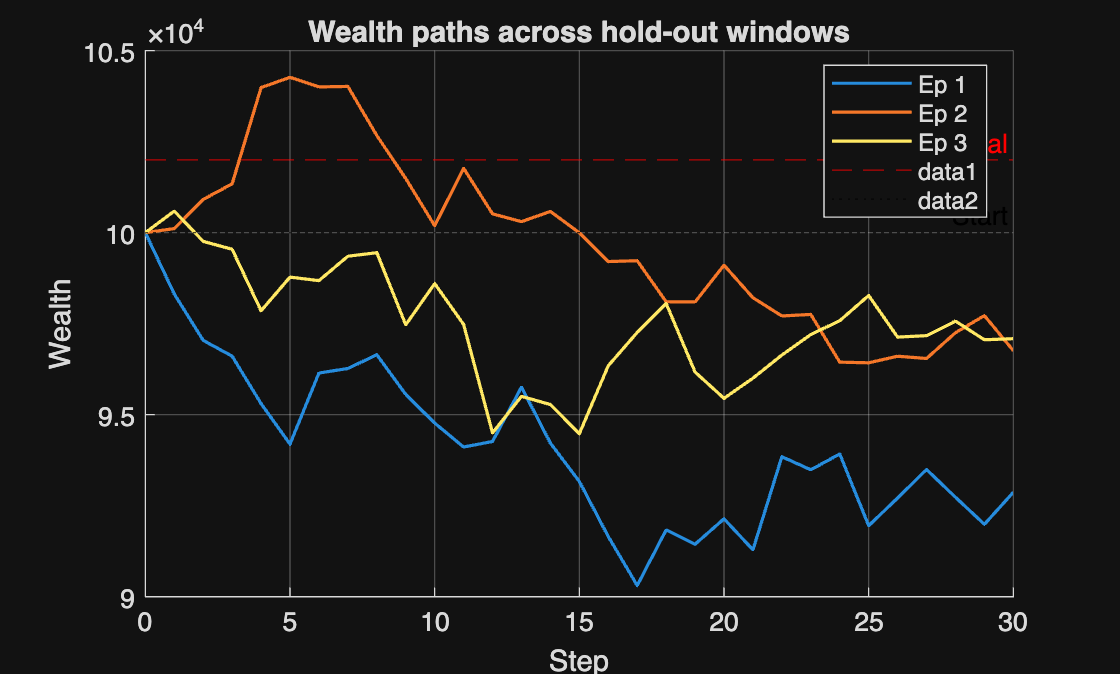

figure('Name','Hold-out wealth paths');
hold on;
for ep = 1:numEvalEpisodes
    if ~isempty(allWealthPaths{ep})
        plot(0:horizonPeriods, allWealthPaths{ep}, 'LineWidth', 1.2, ...
            'DisplayName', sprintf('Ep %d', ep));
    end
end
yline(goalWealth, '--r', 'Goal');
yline(initialWealth, ':k', 'Start');
xlabel('Step'); ylabel('Wealth');
title('Wealth paths across hold-out windows');
legend('Location','best'); grid on;

## Local Functions

function Return = inputTestData(filename)
    pricesTT = readtable(filename, 'VariableNamingRule', 'preserve');
    Return   = price2ret(pricesTT, 'Method', 'continuous');
end

